# RLC Low-Pass Filter Numerical Simulation

Course: EEE 415 – Numerical Methods II

Project: Frequency Response Analysis of an RLC Low-Pass Filter

# TIMELINE 1

## Defining Circuit Parameters

clc;            % Clear command window
clear;          % Remove variables from workspace
close all;      % Close all open figures

R = 1000;        % Resistance (Ohms)
L = 10e-3;       % Inductance (Henries) -> 10 mH
C = 1e-6;        % Capacitance (Farads) -> 1 uF


## Defining Frequency Range for Analysis

f_min = 10;          % Minimum frequency (Hz)
f_max = 1e5;         % Maximum frequency (100 kHz)
N = 1000;            % Number of frequency points

f = linspace(f_min, f_max, N);   % Frequency vector

## Converting Frequency to Angular Frequency

w = 2*pi*f;         % Angular frequency (rad/s)

%% 4. Define Laplace Variable s = jω

s = 1j*w;           % j = imaginary unit

disp("Environment and circuit parameters successfully initialized.");

Environment and circuit parameters successfully initialized.


# TIMELINE 2

## Defining Transfer Function of RLC Low-Pass Filter



H = 1 ./ (L*C*s.^2 + R*C*s + 1);    % Transfer function H(s)


## Computing Gain in Decibels

 
Gain_dB = 20*log10(abs(H));         % Magnitude in dB


## Plotting the Bode Magnitude Plot

figure;

semilogx(f, Gain_dB,'LineWidth',2)
grid on

xlabel('Frequency (Hz)')
ylabel('Gain (dB)')
title('Bode Magnitude Plot of RLC Low-Pass Filter')


## Saving Figure for Report and Presentation

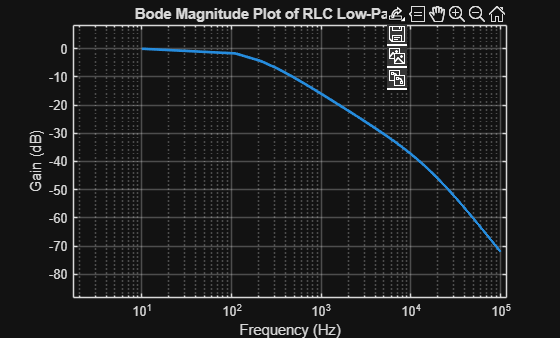

saveas(gcf,'Bode_Magnitude_Plot.png')


disp("Bode plot successfully generated and saved.")

Bode plot successfully generated and saved.


# TIMELINE 3

## Forward Difference Numerical Derivative

% Step size
h = f(2) - f(1);

% Initialize derivative vector
ForwardDiff = zeros(1,length(Gain_dB));

% Compute Forward Difference
for i = 1:length(Gain_dB)-1
    ForwardDiff(i) = (Gain_dB(i+1) - Gain_dB(i)) / h;
end

% Handle last element
ForwardDiff(end) = ForwardDiff(end-1);


## Detecting Numerical Cutoff Frequency

[minSlope, idx] = min(ForwardDiff);   % Find steepest slope
fc_forward = f(idx);                  % Cutoff frequency estimate

fprintf('Forward Difference Estimated Cutoff Frequency: %.2f Hz\n', fc_forward);

Forward Difference Estimated Cutoff Frequency: 110.09 Hz


## Plotting Forward Difference Slope

figure

semilogx(f, ForwardDiff,'LineWidth',2)
grid on
hold on

% Mark cutoff frequency on plot
plot(fc_forward, minSlope,'ro','MarkerSize',8,'LineWidth',2)

xlabel('Frequency (Hz)')
ylabel('d(Gain)/df')
title('Forward Difference Approximation of Gain Slope')

legend('Forward Difference Slope','Estimated Cutoff Frequency')


## Saving the forward difference Figure

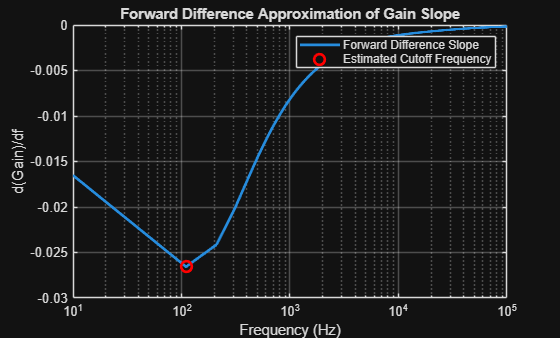

saveas(gcf,'Forward_Difference_Slope.png')


disp("Forward difference slope plotted and cutoff frequency detected.")

Forward difference slope plotted and cutoff frequency detected.


# TIMELINE 4

## Backward Difference Numerical Derivative

% Initialize derivative vector
BackwardDiff = zeros(1,length(Gain_dB));

% Compute Backward Difference
for i = 2:length(Gain_dB)
    BackwardDiff(i) = (Gain_dB(i) - Gain_dB(i-1)) / h;
end

% Handle first element
BackwardDiff(1) = BackwardDiff(2);

## Detecting the backward Numerical Cutoff Frequency


[minSlope_b, idx_b] = min(BackwardDiff);
fc_backward = f(idx_b);

fprintf('Backward Difference Estimated Cutoff Frequency: %.2f Hz\n', fc_backward);

Backward Difference Estimated Cutoff Frequency: 210.18 Hz


## Plotting the Backward Difference Slope


figure

semilogx(f, BackwardDiff,'LineWidth',2)
grid on
hold on

% Mark cutoff point
plot(fc_backward, minSlope_b,'ro','MarkerSize',8,'LineWidth',2)

xlabel('Frequency (Hz)')
ylabel('d(Gain)/df')
title('Backward Difference Approximation of Gain Slope')

legend('Backward Difference Slope','Estimated Cutoff Frequency')


## Saving the backward difference Figure

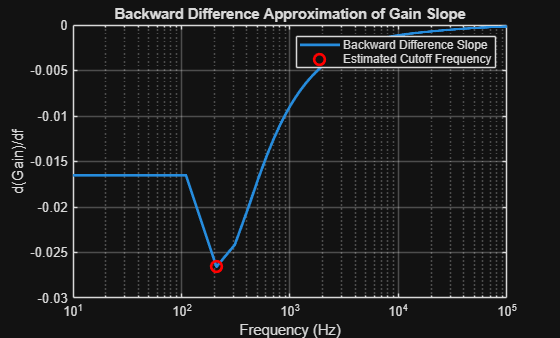


saveas(gcf,'Backward_Difference_Slope.png')


disp("Backward difference slope plotted and saved.")

Backward difference slope plotted and saved.


# TIMELINE 5

## Central Difference Numerical Derivative


% Initialize derivative vector
CentralDiff = zeros(1,length(Gain_dB));

% Compute Central Difference
for i = 2:length(Gain_dB)-1
    CentralDiff(i) = (Gain_dB(i+1) - Gain_dB(i-1)) / (2*h);
end

% Handle boundary values
CentralDiff(1) = CentralDiff(2);
CentralDiff(end) = CentralDiff(end-1);


## Detecting the central difference Numerical Cutoff Frequency


[minSlope_c, idx_c] = min(CentralDiff);
fc_central = f(idx_c);

fprintf('Central Difference Estimated Cutoff Frequency: %.2f Hz\n', fc_central);

Central Difference Estimated Cutoff Frequency: 210.18 Hz


## Plotting Central Difference Slope


figure

semilogx(f, CentralDiff,'LineWidth',2)
grid on
hold on

plot(fc_central, minSlope_c,'ro','MarkerSize',8,'LineWidth',2)

xlabel('Frequency (Hz)')
ylabel('d(Gain)/df')
title('Central Difference Approximation of Gain Slope')

legend('Central Difference','Estimated Cutoff Frequency')


## Saving the central difference Figure

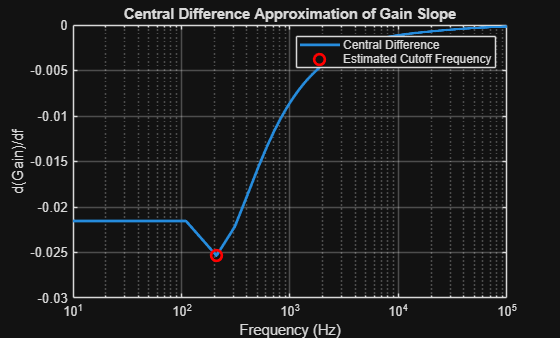

saveas(gcf,'Central_Difference_Slope.png')

# TIMELINE 6

## Step Size Analysis



%% Step Size Analysis for Central Difference Derivative

% Define step sizes (Hz)
step_sizes = [2 5 10];  

% Prepare figure
figure;
hold on;
grid on;

colors = {'r', 'g', 'b'};  % line colors for each step size

for k = 1:length(step_sizes)
    h_step = step_sizes(k);
    
    % Generate frequency vector with this step size
    f_step = f_min:h_step:f_max;
    
    % Interpolate Gain at these frequency points for smooth calculation
    Gain_step = interp1(f, Gain_dB, f_step, 'linear');
    
    % Ensure at least 3 points for central difference
    if length(f_step) < 3
        continue;
    end
    
    % Compute central difference derivative
    h_vec = diff(f_step);  % spacing between points
    centralDiff = (Gain_step(3:end) - Gain_step(1:end-2)) ./ (2*h_vec(1:end-1));
    
    % Handle boundaries by repeating nearest slope
    centralDiff = [centralDiff(1), centralDiff, centralDiff(end)];
    
    % Plot
    semilogx(f_step, centralDiff, 'LineWidth', 2, 'Color', colors{k}, ...
        'DisplayName', ['h = ' num2str(h_step) ' Hz']);
end

% Labels and title
xlabel('Frequency (Hz)');
ylabel('d(Gain)/df');
title('Effect of Step Size on Central Difference');
legend('show', 'FontSize', 8, 'Location', 'best');
hold off;


## Saving the Figure for the step size analysis

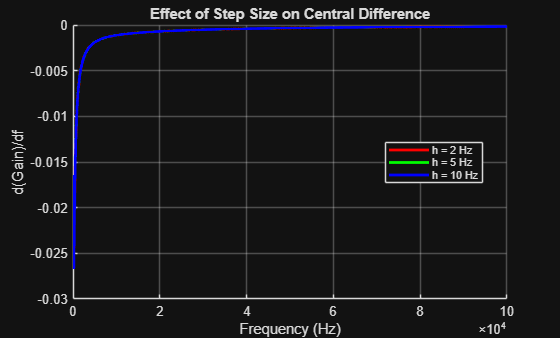


saveas(gcf,'Step_Size_Analysis.png')


disp("Step size analysis completed and figure saved.")

Step size analysis completed and figure saved.


# TIMELINE 7

## Computing the Analytical Cutoff Frequency



fc_analytical = 1/(2*pi*sqrt(L*C));

fprintf('Analytical Cutoff Frequency: %.2f Hz\n', fc_analytical);

Analytical Cutoff Frequency: 1591.55 Hz


## Creating the Comparison Table


Method = ["Analytical";
          "Forward Difference";
          "Backward Difference";
          "Central Difference"];

Cutoff_Frequency_Hz = [fc_analytical;
                       fc_forward;
                       fc_backward;
                       fc_central];

ComparisonTable = table(Method, Cutoff_Frequency_Hz);

disp("Cutoff Frequency Comparison Table:")

Cutoff Frequency Comparison Table:


disp(ComparisonTable)

           Method            Cutoff_Frequency_Hz
    _____________________    ___________________

    "Analytical"                   1591.5       
    "Forward Difference"           110.09       
    "Backward Difference"          210.18       
    "Central Difference"           210.18       



## Saving Table to File


writetable(ComparisonTable,'Cutoff_Frequency_Comparison.csv');

disp("Comparison table saved successfully.")

Comparison table saved successfully.


# TIMELINE 7

%%saving figures
